Only conserves energy for dx = 1. whyyy

Np changes damping rate on Landau damping?? Whyyyy?

clear
clc

%1 is Landau Damping, 2 is two-stream instability
mode = 1;

Nx = 30;
Np = 10000; %Must be even

c = 1; %speed of light, %%%WARNING: made it 1 for consistency with paper
T0 = 1;
Kb = 0.00001; %boltzmann constant, %%%WARNING: made it 1 for consistency with paper (or not)
rho0 = 1;

q0 = 1; %Fundamental charge (proton/ion)
e0 = 1; %permittivity of free space, %%%WARNING: made it 1 for consistency with paper
mu = 1; %Magnetic constant
m_electron = 1;
m_ion = 2000;

x = zeros(Np, 1);
v = zeros(Np, 1);
vt = zeros(Np, 1);
q = zeros(Np, 1);
Ep = zeros(Np, 1);

t_max = 20;
dt = .1;
E = zeros(Nx, 1);
Et = zeros(Nx, 1);

J = zeros(Nx, 1); %It's J with a curved hat in the paper
M = zeros(Nx,Nx);

store_electric_field = false;

Mode specific initialization

if(mode == 1)
    v_max_electron = 8;
    v_max_ion = 0;
    Lx = 4*pi;
    m = [ones(Np/2, 1)*m_electron; ones(Np/2, 1)*m_ion];
    q(1:Np/2) = -q0; 
    q(Np/2+1:Np) = q0;
    scaling = rho0*Lx/sum(abs(q)); %Not sure if sum of q or m. I think m makes it more
    %consistent with Np changes but magnitude becomes weird.
    m = m*scaling;
    q = q*scaling;
    x(:,1) = rand(Np,1)*Lx;
    a_electrons = m_electron/(2*Kb*T0);
    a_ions = m_ion/(2*Kb*T0);
    v(1:Np/2) = sat(boltzmann(a_electrons, Np/2), v_max_electron);
    v(Np/2+1:Np) = sat(boltzmann(a_ions, Np/2), v_max_ion);
    temp = linspace(0,2*pi,Nx+1);
    E = -0.2*sin(temp(1:Nx))';
    store_electric_field = true;
    store_kinetic_energy = true;
    Eh = zeros(Nx,0);
    Ke = zeros(Nx,0);
end
if(mode == 2)
    v_max_electron = inf;
    v_max_ion = inf;
    Lx = 4*pi;
    m = [ones(Np/2, 1)*m_electron; ones(Np/2, 1)*m_ion];
    q(1:Np/2,1) = -q0; 
    q(Np/2+1:Np,1) = q0;
    scaling = rho0*Lx/sum(abs(q)); %Not sure if sum of q or m
    m = m*scaling;
    q = q*scaling;
    x(:,1) = rand(Np,1)*Lx;
    a_electrons = m_electron*scaling/(2*Kb*T0);
    a_ions = m_ion*scaling/(2*Kb*T0);
    v(1:Np/2,1) = sat(boltzmann(a_electrons, Np/2), v_max_electron)+1;
    v(Np/2+1:Np,1) = sat(boltzmann(a_ions, Np/2), v_max_ion)-1;
    E = zeros(size(E));
    store_electric_field = true;
    store_kinetic_energy = true;
    store_magnetic_field = true;
    Eh = zeros(Nx,0);
    Bh = zeros(Nx,0);
    Ke = zeros(Nx,0);
end

dx = Lx/Nx;
t = 0;

Construct Matrices

beta = (q./m)*(dt/2);
c1 = 1/(dx);
c2 = 2/(c*dt);
c3 = 4*pi/c;

A = -c2*eye(Nx); %A is the system matrix without the mass terms
%A = sparse(A);

Af = zeros(Nx, Nx); %Af will be the full system matrix
C = zeros(Nx, 1); %C will be the system vector

Time advancement

%outer loop
outerTic = tic;
while (t < t_max)
    if(store_electric_field)
        Eh = [Eh, E];
    end
    if(store_kinetic_energy)
        Ke = [Ke, 0.5*sum(m.*(v.*v))];
    end
    %Step 1
    x = x + sat(dt*v,dx);
    %x = x + dt*v;
    %Periodic boundary condition
    x = mod(x,Lx);
    %Step 4:::tested same as double loop
    %Empty currents
    g = getParticleGridCell(x(:,1), Lx, Nx);
    gp = mod(g+1, Nx);
    wg = evaluateWeight(x, g, Lx, Nx);
    wgp = evaluateWeight(x, gp, Lx,Nx);
    dJg = (q.*v.*wg);
    dJgp = (q.*v.*wgp);
    Jg = accumarray(g+1,dJg);
    Jgp = accumarray(gp+1,dJgp);
    J = Jg+Jgp;
    J = J/dx; %Error in paper fix
    %Step 5
    %Empty mass matrices
    pConst = beta.*q;
    %Compute mass matrices:::tested same as triple loop
    Mggp = accumarray(g+1, pConst.*wg.*wgp);
    Mgg = accumarray(g+1, pConst.*wg.*wg);
    Mgpgp = accumarray(gp+1, pConst.*wgp.*wgp);
    M = diag(Mgg+Mgpgp);
    for i = 1:Nx
        M(i,mod(i,Nx)+1) = M(i,mod(i,Nx)+1) + Mggp(i);
        M(mod(i,Nx)+1,i) = M(mod(i,Nx)+1,i) + Mggp(i); 
    end
    M = M/dx;
    %Compute system vector
    Af = A-c3*M;
    %Compute system vector
    C = -c2*E+c3*J;
    %Solve system
    Et = linsolve(Af,C);
    %Step 7
    Ep = evaluateField(Et, x, Lx, Nx);
    %Step 8
    v = 2*beta.*Ep + v;
    %Update fields
    E = 2*Et-E;
    t = t + dt;
end
toc(outerTic)

Elapsed time is 35.048547 seconds.


Plot electric field variation

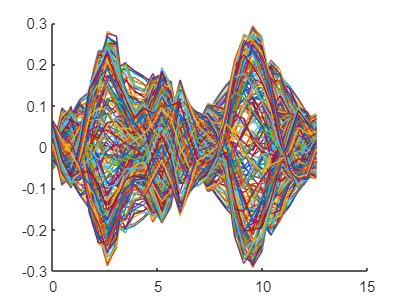

figure(1);
clf
hold on
for i = 1:size(Eh, 2)
    plot(linspace(0,Lx,Nx), Eh(:,i));
end

Plot electric field energy in time

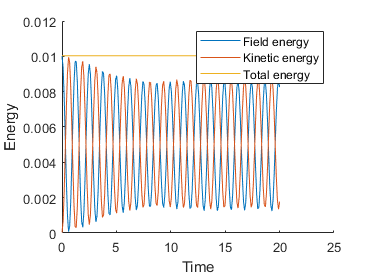

figure(2);
clf
hold on
energy = [];
for i = 1:size(Eh, 2)
    energy = [energy, e0*0.5*dx*(sum(Eh(:,i).*Eh(:,i))/(4*pi))]; %%%%WARNING, formula should be /e0 inside but ignore for last year comparison
end
plot(linspace(0, t, size(Eh, 2)), energy);
plot(linspace(0, t, size(Eh, 2)), Ke);
plot(linspace(0, t, size(Eh, 2)), energy + Ke);
legend('Field energy', 'Kinetic energy', 'Total energy');
xlabel('Time')
ylabel('Energy')

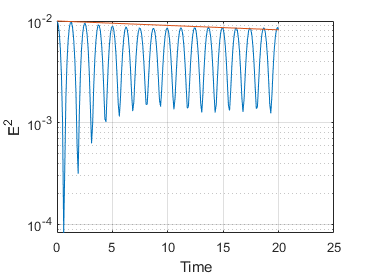

%plot(0:dt:t_max, energy);

figure(3);
clf
semilogy(linspace(0, t, size(Eh, 2)), energy);
hold on
semilogy(linspace(0, t, size(Eh, 2)), energy(1)*exp(-1e-2*linspace(0, t, size(Eh, 2))));
grid on
xlabel('Time')
ylabel('E^{2}')

Evaluate field

function F = evaluateField(field, x, Lx, Nx)
    f = fit(linspace(0,Lx,Nx+1)', [field; field(1,:)], 'Linear');
    F = f(x);
end


Particle grid cell

%Returns 0 indexedddd
function g = getParticleGridCell(x, Lx, Nx)
    dx = Lx/Nx;
    g = floor(x/dx);
end

Evaluate Wpg

%%%g is 0 indexedddd
function W = evaluateWeight(xp, g, Lx, Nx)
    dx = Lx/Nx;
    xg = g*dx;
    %Periodic condition
    cond1 = (g==0).*(xp+dx>Lx);
    W = max(cond1.*(1 - abs(Lx-xp)/dx)+(~cond1).*(1 - abs(xp-xg)/dx), 0);
end

Generate 1D maxwell boltzmann distribution

function y = boltzmann(a, n)
    x = rand([1,n]);
    y = erfinv(2*x-1)/sqrt(a); 
end

Saturation funtion (to +- delta)

function y = sat(x, delta)
   y = min(max(x, -delta), delta); 
end